# Part 7: Sensitivity analysis

Deprecated. Use pipeline7_remote for sensitivity analysis


%Generate/load the data
if runPart7
    args.p7.v_default = v_default;
    dat7 = part7_generation(args.p7)
else
    if ~exist('dat7','var')
        load([datadir '\dat7.mat']);
    end
end

Error using load
Unable to read file 'C:\sync\biomes\cellulose\optima\clean_version\data\dat7.mat'. No such file or directory.

7B: observe what happens when you change just the KM or Kcat

if runPart7b
    args.p7.v_default = v_default;
    args.p7.v_default.kcat_cel = 27;
    args.p7.v_default.km_cel = 0.03;
    args.p7.v = args.p7.v_default;
    args.p7.v.alpha = exp(-4.3);
    dat7b = part7b_generation(args.p7);
    args.p7.v.km_cel = args.p7.v_default.km_cel * 10;
    temp = part7b_generation(args.p7);
    dat7b = vertcat(dat7b,temp);
    args.p7.v.km_cel = args.p7.v_default.km_cel * 100;
    temp = part7b_generation(args.p7);
    dat7b = vertcat(dat7b,temp);
    args.p7.v.km_cel = args.p7.v_default.km_cel / 10;
    temp = part7b_generation(args.p7);
    dat7b = vertcat(dat7b,temp);
    args.p7.v.km_cel = args.p7.v_default.km_cel / 100;
    temp = part7b_generation(args.p7);
    dat7b = vertcat(dat7b,temp);
    args.p7.v.km_cel = args.p7.v_default.km_cel;
    args.p7.v.kcat_cel = args.p7.v_default.kcat_cel * 10;
    temp = part7b_generation(args.p7);
    dat7b = vertcat(dat7b,temp);
    args.p7.v.kcat_cel = args.p7.v_default.kcat_cel * 100;
    temp = part7b_generation(args.p7);
    dat7b = vertcat(dat7b,temp);
    args.p7.v.kcat_cel = args.p7.v_default.kcat_cel / 10;
    temp = part7b_generation(args.p7);
    dat7b = vertcat(dat7b,temp);
    args.p7.v.kcat_cel = args.p7.v_default.kcat_cel / 100;
    temp = part7b_generation(args.p7);
    dat7b = vertcat(dat7b,temp);

    runPart7b = false;
else
    if ~exist('dat7b','var')
        load([datadir '\dat7b.mat']);
    end
end

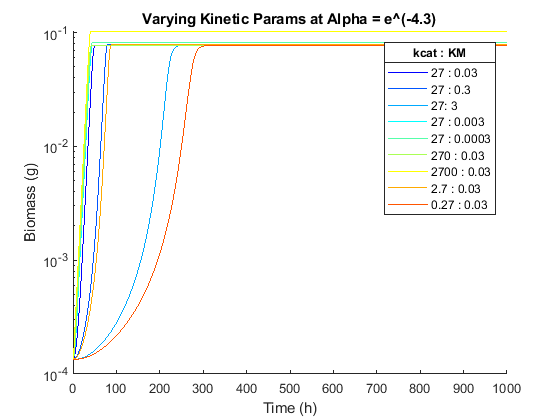

figure();
hold on;
[nrows,~] = size(dat7b);
colors = jet(nrows);
for i = 1:nrows
    plot(dat7b.t{i},dat7b.biomass{i},'color',colors(i,:));
end
hold off;
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca,'YScale','log');
title('Varying Kinetic Params at Alpha = e\^(-4.3)');
leg = legend({'27 : 0.03' '27 : 0.3' '27: 3' '27 : 0.003' '27 : 0.0003' '270 : 0.03' '2700 : 0.03' '2.7 : 0.03' '0.27 : 0.03' });
title(leg,'kcat : KM');

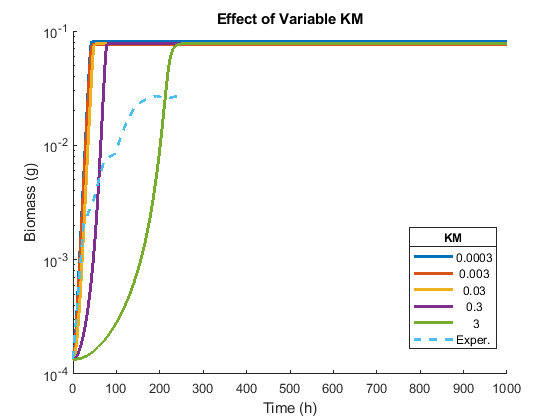


%KM variation only
row1 = dat7b(1,:);
kmrows = dat7b(dat7b.km_cel ~= row1.km_cel,:);
kmrows = vertcat(row1,kmrows);
kmrows = sortrows(kmrows,'km_cel');
[nrows,~] = size(kmrows);
figure();
hold on;
for i = 1:nrows
    plot(kmrows.t{i},kmrows.biomass{i},'linewidth',2);
end
plot(ivd.denhaan.ctdat,ivd.denhaan.gdw,'--','lineWidth',2);
hold off;
set(gca,'YScale','log');
xlabel('Time (h)');
ylabel('Biomass (g)');
legstr = num2str(kmrows.km_cel);
leg = legend([legstr;'Exper.'],'location','best');
title(leg,'KM');
title('Effect of Variable KM')

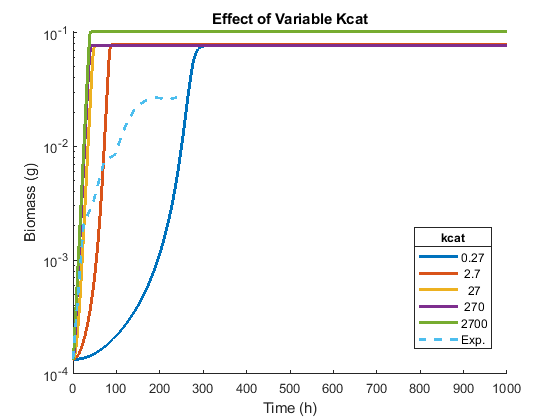


%Kcat variation only
row1 = dat7b(1,:);
kcatrows = dat7b(dat7b.kcat_cel ~= row1.kcat_cel,:);
kcatrows = vertcat(row1,kcatrows);
kcatrows = sortrows(kcatrows,'kcat_cel');
[nrows,~] = size(kcatrows);
figure();
hold on;
for i = 1:nrows
    plot(kcatrows.t{i},kcatrows.biomass{i},'linewidth',2);
end
plot(ivd.denhaan.ctdat,ivd.denhaan.gdw,'--','lineWidth',2);
hold off;
set(gca,'YScale','log');
xlabel('Time (h)');
ylabel('Biomass (g)');
legstr = num2str(kcatrows.kcat_cel);
leg = legend([legstr;'Exp.'],'location','best');
title(leg,'kcat');
title('Effect of Variable Kcat')